# Results of AR modeling

names = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

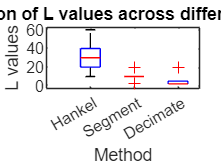

% Create a new figure
figure;
hold on;

% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 1), best_dimensions_segment(:, 1), best_dimensions_decimate(:, 1)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('L values');
title('Distribution of L values across different methods');

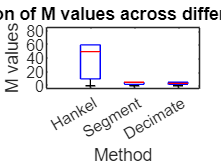


% Create a new figure
figure;
hold on;


% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 2), best_dimensions_segment(:, 2), best_dimensions_decimate(:, 2)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('M values');
title('Distribution of M values across different methods');

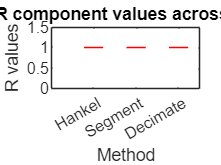

% Create a new figure
figure;
hold on;

new_fields = size(best_dimensions_hankel,1);

% Define a set of colors or markers for different fields
colors = lines(new_fields); % Using lines colormap for distinct colors
jitterAmount = 0.3;

% Prepare the data for boxplot
data = [best_comp_hankel(:, 1), best_comp_segment(:, 1), best_comp_decimate(:, 1)];
group = [ones(size(best_comp_hankel, 1), 1); 
         2 * ones(size(best_comp_segment, 1), 1); 
         3 * ones(size(best_comp_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('R values');
title('Distribution of R component values across different methods');

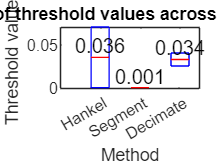

% Create a new figure
figure;
hold on;

% Prepare the data for boxplot
data = [best_thresh_hankel(:, 1); best_thresh_segment(:, 1); best_thresh_decimate(:, 1)];
group = [ones(size(best_thresh_hankel, 1), 1); 
         2 * ones(size(best_thresh_segment, 1), 1); 
         3 * ones(size(best_thresh_decimate, 1), 1)];

% Create the boxplot
boxplot(data, group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Calculate medians
medians = grpstats(data, group, 'median');

% Label the plot
xlabel('Method');
ylabel('Threshold values');
title('Distribution of threshold values across different methods');

% Add numbers next to the medians
positions = [1, 2, 3];
for i = 1:length(medians)
    text(positions(i), medians(i), sprintf('%.3f', medians(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% Adjust Y-axis limits to fully use the vertical axis
ylim auto; % Automatically set the limits based on the data

hold off;

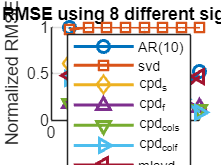

% Prepare the data
rmseValues = zeros(8,7);
for i = 1:7
    rmseValues(:,i) = squeeze(ex9gt1mean(3,i+1,:));
end
rmseValuesNorm = rmseValues ./ max(rmseValues, [], 2);

% Create a new figure
figure;
hold on;

% Define colors and markers
colors = lines(7); % Use MATLAB's lines colormap
markers = {'o', 's', 'd', '^', 'v', '>', '<'};

% Plot each normalized RMSE
for i = 1:7
    plot(rmseValuesNorm(:,i), 'Color', colors(i,:), 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', names{i});
end

% Add grid, labels, and title
grid on;
legend(names, 'location', 'northeast');
xlabel('Parameter set');
ylabel('Normalized RMSE');
title('Normalized RMSE using 8 different signal parameters');

% Release the hold on the figure
hold off;

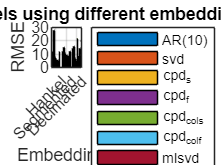

% Prepare the data
perfHankel = zeros(8,7);
perfSegment = zeros(8,7);
perfDecimate = zeros(8,7);

measure =3;

measureNames = ["mean", "SD", "RMSE", "Relative Error", "L2 Relative Error","Runtime"];

for i = 1:7
    perfHankel(:,i) = squeeze(ex9gt1mean(measure,i+1,:));
    perfSegment(:,i) = squeeze(ex11gt1mean(measure,i+1,:));
    perfDecimate(:,i) = squeeze(ex13gt1mean(measure,i+1,:));
end

% Example data (replace with your actual data)
perfHankelMed = mean(perfHankel, 1);
perfSegmentMed = mean(perfSegment, 1);
perfDecimateMed = mean(perfDecimate, 1);

% Combine the data into one matrix
sortedData = [perfHankelMed; perfSegmentMed; perfDecimateMed];

% Model names
modelNames = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

% Create a new figure
figure;

% Plot the data as grouped bars
bar(sortedData);

% Set the legend and labels
legend(modelNames, 'Orientation', 'vertical', 'Location', 'eastoutside');
xticks([1 2 3]);
xticklabels({'Hankel', 'Segmented', 'Decimated'});
xlabel('Embeddings');
ylabel([measureNames(measure)]);
title(measureNames(measure)+" of models using different embeddings");
grid on;

ex9all = mean(ex9gt1mean,3)

ex9all =     5.1659    0.6381    2.8461    0.1277    1.3609    1.3944    0.5503    1.5731
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0   11.5463   27.2161    7.2940    5.8483    5.1958    5.4302   11.6371
         0    7.6407   10.3654    4.1756    3.5668    2.2896    1.8776    7.7253
         0    8.0325   10.7912    4.4312    3.8929    2.5443    2.1403    8.1507
         0    0.0772    2.9293    0.1473    0.1404    0.1333    0.1778    0.0807


ex11all = mean(ex11gt1mean,3)

ex11all =     4.7197   -0.0669   -2.0323   -1.5693    0.3409    5.4674    5.4674   -0.0676
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0   11.8202   14.5701   10.4880    5.7746    8.6586    8.6586   11.8203
         0    4.3253    6.6989    3.8138    2.1140    3.5255    3.5255    4.3252
         0    4.6431    7.1256    4.1133    2.3933    3.9481    3.9481    4.6429
         0    0.0698    0.3586    0.0924    0.0932    0.0784    0.0815    0.0748


ex13all = mean(ex13gt1mean,3)

ex13all =     5.7285    3.9886   -1.3136    1.7690    1.1526    1.2166   10.0413    4.0310
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0   14.4165   15.6982    6.3598    5.4442   21.7413    8.0464   14.2739
         0    3.4991    5.3520    2.1913    3.1682    9.3408    4.5277    3.3804
         0    3.9269    5.6699    2.5010    3.4537    9.7075    4.9453    3.7929
         0    0.0733    0.3212    0.0925    0.0907    0.0850    0.0818    0.0740


ex18all = mean(ex18gt1mean,3)

ex18all = 1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


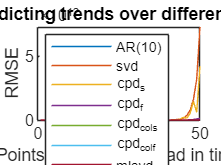


figure;


plot(ex18all(:,1));
hold on;
plot(ex18all(:,2));
plot(ex18all(:,3));
plot(ex18all(:,4));

plot(ex18all(:,5));
plot(ex18all(:,6));
plot(ex18all(:,7));

hold off;

legend (names, 'location', 'northwest');
xlabel('Points forecasted ahead in time');
ylabel('RMSE');
title('RMSE values predicting trends over different parameter setups');